# **Procesamiento de Imagenes Digitales**

# **Taller 6**

## Cargar imagen

Cargue la imagen de rayosX 'hand.tif', y visualicela en la `figura 1`.

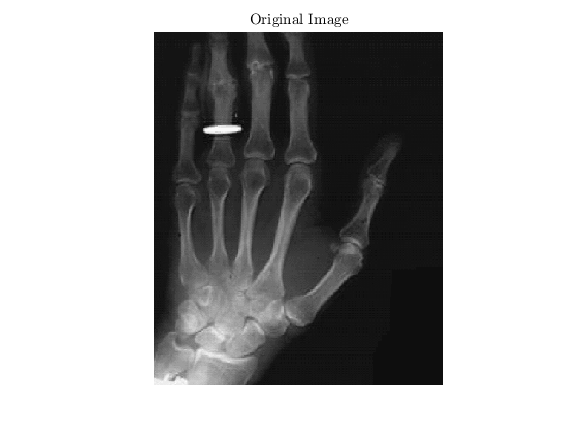

I = imread('hand.tif');
figure(1);
imshow(I);title('Original Image','Interpreter','Latex');

## Espectro de Fourier

Asigne el espectro de Fourier centrado a la variable, mejore su contraste, y visualice en la `figura 2 `en un subplot horizontal.

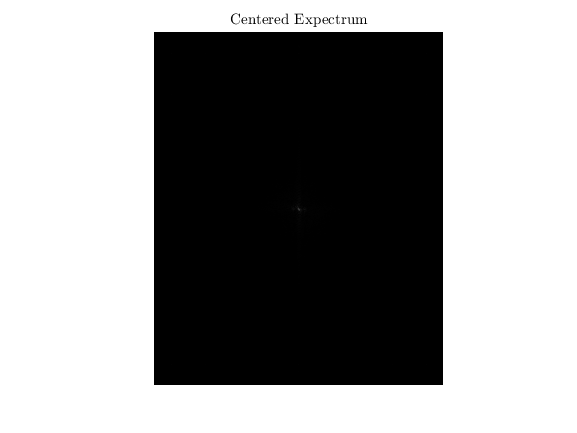

F = fft2(I);
Sc = im2uint8(mat2gray(abs(fftshift(fft2(I)))));
figure(2);
imshow(Sc);title('Centered Expectrum','Interpreter','Latex');

## Filtros espaciales

Defina un kernel de Sobel y otro de Prewitt. No use punto y coma para imprimir el resultado.

ksobel = [1 0 -1; ...
          2 0 -2; ...
          1 0 -1]

ksobel =      1     0    -1
     2     0    -2
     1     0    -1


kprewitt = [1 0 -1; ...
            1 0 -1; ...
            1 0 -1]

kprewitt =      1     0    -1
     1     0    -1
     1     0    -1


En un subplot horizontal, en la `figura 3`, visualice los dos filtros utilizando la función `freqz2`.

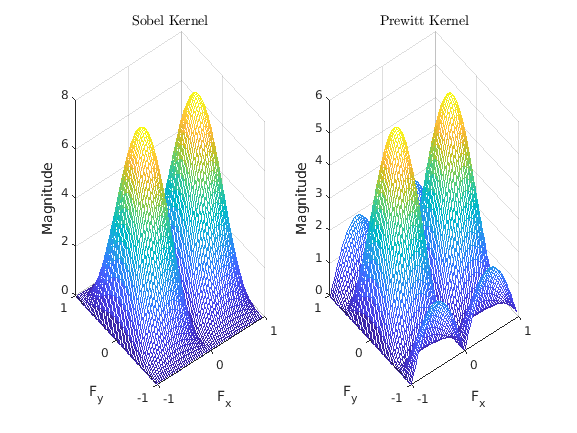

figure(3);
subplot(1,2,1);freqz2(ksobel);title('Sobel Kernel','Interpreter','Latex');
subplot(1,2,2);freqz2(kprewitt);title('Prewitt Kernel','Interpreter','Latex');

## Escalado de kernels con padding

Escale los kernels al tamaño de la imagen, utilizando las funciones: `[MN] = 2*size()` y `freqz2(filtro,MN(1),MN(2))`, y visualice como imagen en un subplot horizontal en la` figura 4`

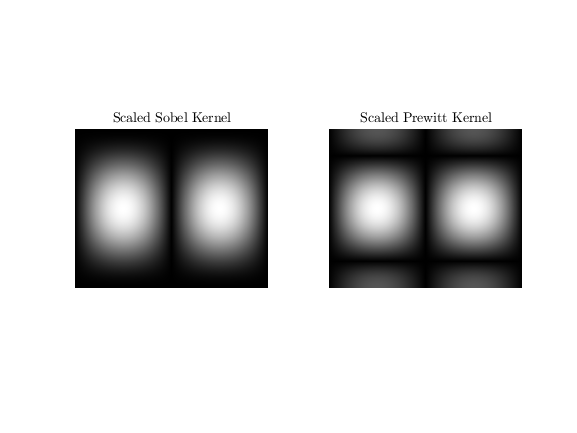

[MN] = 2*size(I);

Kesobel = freqz2(ksobel,MN(1),MN(2));
Keprewitt = freqz2(kprewitt,MN(1),MN(2));

KEsobel = im2uint8(mat2gray(abs(Kesobel)));
KEprewitt = im2uint8(mat2gray(abs(Keprewitt)));

figure(4);
subplot(1,2,1);imshow(KEsobel);title('Scaled Sobel Kernel','Interpreter','Latex');
subplot(1,2,2);imshow(KEprewitt);title('Scaled Prewitt Kernel','Interpreter','Latex');

## **Filtrado en el dominio frecuencial**

Revierta el centrado de los filtros, y calcule la transformada de Fourier de la Imagen en función del padding del kernel, aplique los filtros (producto punto a punto entre la transformada de Fourier y el filtro), vuelva al dominio espacial y visualice como imagen en un subplot horizontal en la `figura 5`.

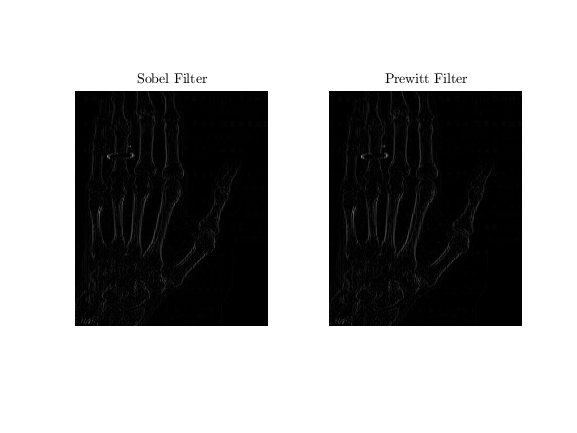

Iksobel = ifftshift(Kesobel);
Ikprewitt = ifftshift(Keprewitt);

[MN] = size(Ikprewitt);
F = fft2(I,MN(1),MN(2));

Filter1 = F.*Iksobel;
Filter2 = F.*Ikprewitt;

I1 = ifft2(Filter1);
I2 = ifft2(Filter2);
I1 = I1(1:476,1:390);
I2 = I2(1:476,1:390);

figure(5);
subplot(1,2,1);imshow(abs(I1),[]);title('Sobel Filter','Interpreter','Latex');
subplot(1,2,2);imshow(abs(I2),[]);title('Prewitt Filter','Interpreter','Latex');

## **Filtrado en el dominio espacial**

Aplique los filtros ya definidos en el dominio espacial y visualice en un subplot horizontal en la `figura 6.`

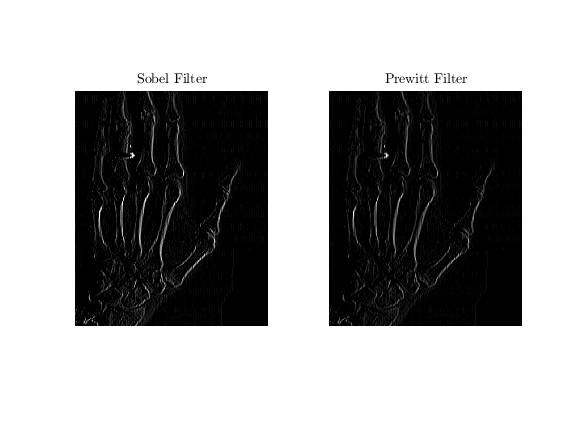

IEs = imfilter(I,ksobel,'symmetric');
IEp = imfilter(I,kprewitt,'symmetric');
figure(6);
subplot(1,2,1);imshow(abs(IEs));title('Sobel Filter','Interpreter','Latex');
subplot(1,2,2);imshow(abs(IEp));title('Prewitt Filter','Interpreter','Latex');

## Conclusión

Aplicar los filtros en el dominio frecuencial para luego hallar su transformada y representarlos en el dominio espacial, resulta en cierta medida igual de conveniente que aplicar los filtros en el dominio espacial, esto debido a que se alcanza a apreciar un poco la perdida de información de pasar de un dominio a otro, aunque esto teoricamente no sucede, en la practica resulta diferente, aunque tenemos que el resultado es bastante similar en ambos casos, abordar los problemas a partir de la transformada de Fourier puede ser una solución solo en algunos casos especificos. 